clear all               
close all               
clc                     

L1 = 0.1;  
L2 = 0.35; 
L3 = 0.35;  
L4 = 0.1; 

L(1) = Link('d', L1, 'a', 0, 'alpha', pi/2);       
L(2) = Link('d', 0, 'a', L2, 'alpha', 0);         
L(3) = Link('d', 0, 'a', L3, 'alpha', 0);         
L(4) = Link('d', 0, 'a', L4, 'alpha', 0);        

robot_arm = SerialLink(L, 'name', '4DOF Robot Arm');

%joint limit
robot_arm.qlim = [[-pi pi]; [-pi/4 7*pi/6]; [-5*pi/6 5*pi/6]; [-5*pi/6 5*pi/6]];

%adjust armbase
robot_arm.base = troty(pi/2); 




%desired position
desired_x = 0; 
desired_y = -0.7;
desired_z = 0.1;

T_desired = transl(desired_x, desired_y, desired_z);

q_solution = robot_arm.ikine(T_desired, 'mask', [1 1 1 0 0 0]); 

disp('Inverse Kinematics Joint Angles for Desired Position:');

Inverse Kinematics Joint Angles for Desired Position:


disp(q_solution);

   -1.7682    0.7892   -1.5855   -0.5875



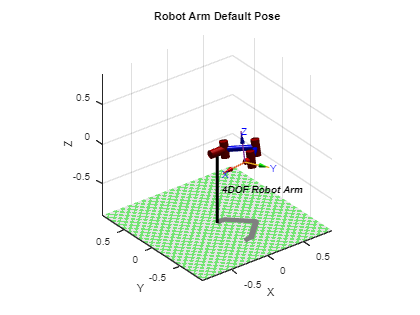

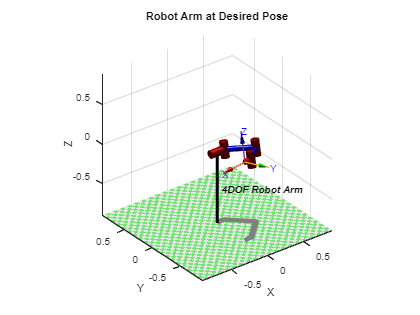


figure();
title('Robot Arm at Desired Pose');
robot_arm.plot(q_solution);